## ENG6 Midterm - Part 1

Student Name (LastName, FirstName): Huynh, Anthony

Student ID: 917359242

#### General Information:

- **You have 20 minutes to answer this question**, after which you will be provided with the second question and another 20 minutes to complete it.

- The midterm must be taken while remaining in the zoom lab meeting room.

- **Submit the code you write here to Zybooks** and **also** submit this **completed mlx workbook** to **Canvas.**

- You can resubmit on Zybooks as many times as you like until you are are satisfied with your solution.

- Once you complete both questions of the Midterm exam, you are free to leave the discussion.

# Question 1

A class has 4 students who score grades on 3 quizes (grades are out of 100). An example of the grades of 3 quizes for these 4 students are as follows:

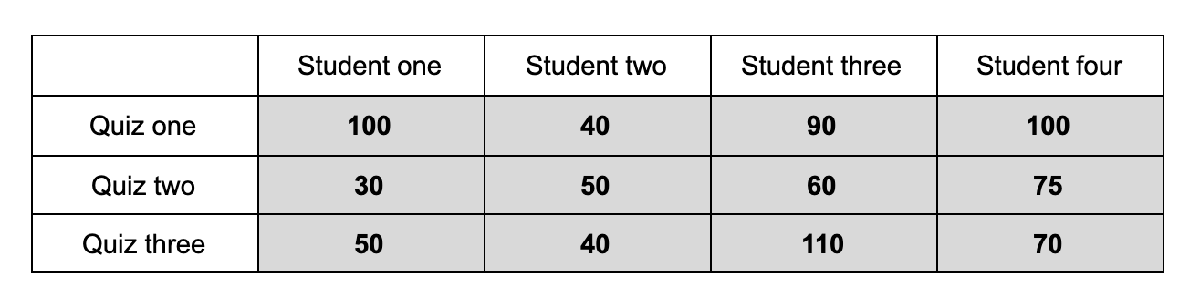

**Write a function that does the following:**

- Replace any grade that is greater than 100 with the lowest grade of the whole class in all quizes (in the example above: replace 110 with 30).

- **Randomly generate** student identification number for these 4 students AND append it at as a new row at the END of the Matrix of quiz grades. These  numbers must be positive integers.

- Sort the grades of each students in each column (low to high) BUT the row of the student numbers must stay at its place without change.

The function call is:

`[outputMatrix] = fixgrades(grades)`

One input argument:   

- `grades` is a 3x4 double precision matrix.

One output arguments:   

-  `outputMatrix is a 4`x4 matrix. 

**Restrictions***: * **Do not use loops or if else statements.**

For example,

grades=[[100,40,90,100];[30,50,60,75];[50,40,110,70]]

grades =    100    40    90   100
    30    50    60    75
    50    40   110    70


For the function call

[outputMatrix] = fixgrades(grades)

outputMatrix =     30    40    30    70
    50    40    60    75
   100    50    90   100
     4     5     3     2


example of output matrix:

    30    40    30    70

    50    40    60    75

   100    50    90   100

     1       5      2      4

function [outputMatrix] = fixgrades(grades)

%an if-else statement for partial credit

  %for i = 1:numel(grades)
  %  if grades(i) > 100
  %     grades(i) = 30;
  %  end
  %end
     
   tt = grades > 100; % logical indexing for
   grades(tt) = 30;   % changing values > 100 to 30
  
 test1 = sort(grades(:,1));
 test2 = sort(grades(:,2));
 test3 = sort(grades(:,3));
 test4 = sort(grades(:,4));
 
 outputMatrix = [test1, test2, test3, test4];
 
 outputMatrix(4,:) = randperm(5,4);

  
end


